# Signal and Image Processing

# Lab 1 - Introduction to Image Analysis with Matlab

addpath('resources', 'scripts');

## Question 1.1

First load the two images. We have provided the code for one (assuming that the image is in the same folder as the "current folder" is)... add the code for the second one yourself!

[im1, map1] = imread('lena_gray.tif');
[im2, ~] = imread('Lena_RGB.tif');

Now display the images. Note that we already provided some of the code to make things look nice. Also do it without those commands such that you understand what they are doing.

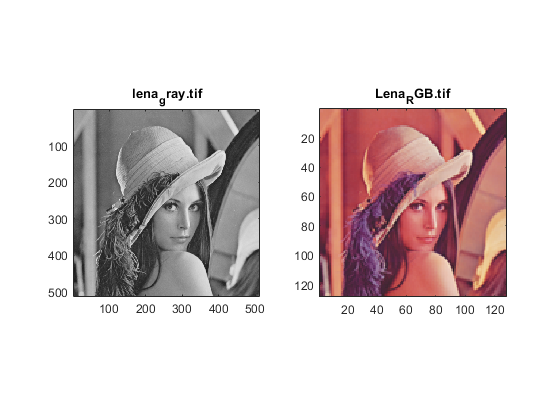

figure(1)
subplot(1,2,1);
image(im1)
colormap(map1)
axis image
title('lena_gray.tif');
subplot(1,2,2);
image(im2)
title('Lena_RGB.tif');
axis image

Now get the properties that are being asked. 

% get the mean pixel value of the grayscale image
pixelMean_gray = mean(mean(mean(ind2rgb(im1,map1))))

pixelMean_gray = 0.4865

pixelMean_rgb = mean(mean(mean(im2)))

pixelMean_rgb = 3.1377e+04


% Another property
info_gray = imfinfo('lena_gray.tif');
width_gray = info_gray.Width

width_gray = 512

height_gray = info_gray.Height

height_gray = 512

colorType_gray = info_gray.ColorType

colorType_gray = 'indexed'

dataType_gray = info_gray.Format

dataType_gray = 'tif'


info_rgb = imfinfo('Lena_RGB.tif');
width_rgb = info_rgb.Width

width_rgb = 128

height_rgb = info_rgb.Height

height_rgb = 128

colorType_rgb = info_rgb.ColorType

colorType_rgb = 'truecolor'

dataType_rgb = info_rgb.Format

dataType_rgb = 'tif'


% etc.

## Question 1.2

First load the image we need

% get rid of the variables that are in the workspace
clear
% load the built-in image (this will generate variables X, caption and map)
load mandrill

Now it is up to you to convert and save it.

% Conversion to RGB goes below
mandrillRGB=ind2rgb(X, map);%complete it
% Saving it goes here
imwrite(mandrillRGB, 'mandrill.bmp');

Next implement the function rgbtograyscale. Create a file named rgbtograyscale.m in the same folder as this file and start with the line as indicated in the assignment. Then use it:

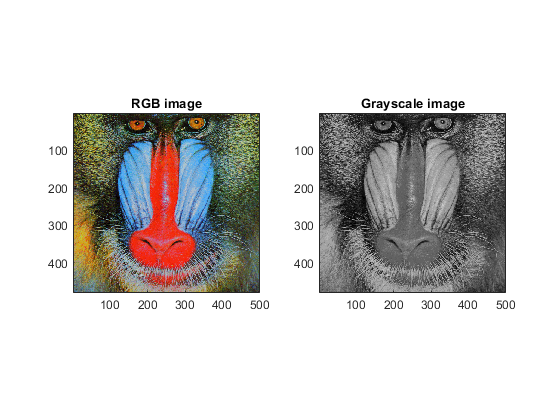

mandrill_gray=rgbtograyscale(mandrillRGB);


figure(2)
subplot(1,2,1);
image(mandrillRGB);
title('RGB image')
axis image
subplot(1,2,2);
image(mandrill_gray);
title('Grayscale image')
axis image

## Question 1.3

First load things and stuff

clear
[im1, map1] = imread('lena_gray.tif');
[im2, map2] = imread('man.bmp');

Display the images and their histograms

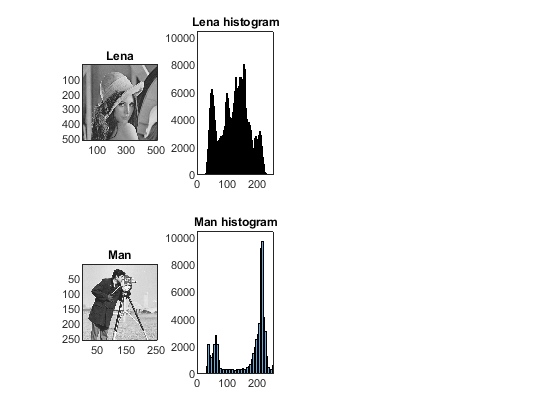

figure(3)
subplot(2,4,1);
% Show first image
image(im1)
colormap(map1)
title('Lena')
axis image
subplot(2,4,2);
% Show the histogram of the first image
histogram(im1)
title('Lena histogram')
axis([0,255,0,10500]); % you might need to correct the axis
subplot(2,4,5);
% Show the second image
image(im2)
colormap(map2)
title('Man')
axis image
subplot(2,4,6);
% Show the histogram of the second image
histogram(im2)
title('Man histogram')
axis([0,255,0,10500]); % you might need to correct something

You should now be able to answer sub a)

*a) the contrast in the 'Man' image is higher. You can see it in the histograms: in the 'Man histogram' there are mainly two intensities with a big gap in between displayed: light and dark. In the 'Lena histogram' all intensities are almost equally distributed and there is no significant gap between its intensities which makes the image rather homogeneous.*

For sub b) you have to implement a function histogramequalization.m. We've provided how we generated the images in the slides below. You can use it to create your own function.

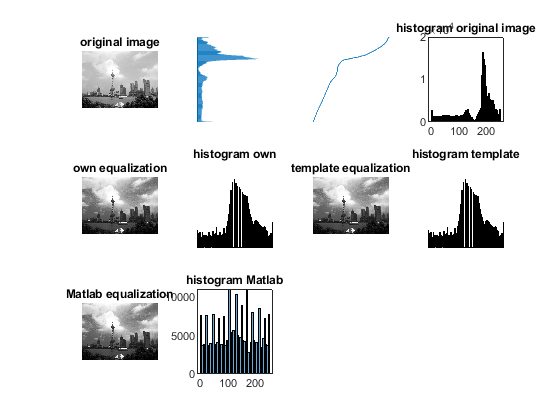

% original image and histogram C:

C=imread('example_shanghai_gray.bmp');

figure
subplot(3,4,1);
imshow(C);
title('original image');
subplot(3,4,2);
hg=histcounts(double(C(:)),-0.5:255.5);
barh(0:255,(hg));
axis([0,7000,-0.5,255.5]);axis off

subplot(3,4,3)
plot(255*cumsum(hg)/241968,0:255);
axis tight off
subplot(3,4,4)
histogram(C);
title('histogram original image');

% Matlab equalized image and histogram F

F=histeq(C); % this is how Matlab does it

subplot(3,4,9)
imshow(F);
title('Matlab equalization');
subplot(3,4,10)
histogram(F);
title('histogram Matlab');

% template equalized image and histogram D
% Manually we can do it as:
T=cumsum(hg);
T=T/T(end);
D=zeros(size(C));
for cnt1=1:size(D,1)
    for cnt2=1:size(D,2)
        D(cnt1,cnt2)=256*T(C(cnt1,cnt2)+1);
    end
end
D=floor(D);

D2=uint8(D);

subplot(3,4,7)
imshow(D2)
title('template equalization');
subplot(3,4,8)
histogram(double(D2(:)),-0.5:255.5);
axis([-0.5,255.5,0,7000]);axis off
title('histogram template');

% own equalized image and histogram E

E=histogramequalization(C);

subplot(3,4,5)
imshow(E)
title('own equalization');
subplot(3,4,6)
histogram(double(E(:)),-0.5:255.5);
axis([-0.5,255.5,0,7000]);axis off
title('histogram own');

Now you need to do the sub c) and d)

% Code goes here

## Question 1.4

implement the linearscale.m function as requested

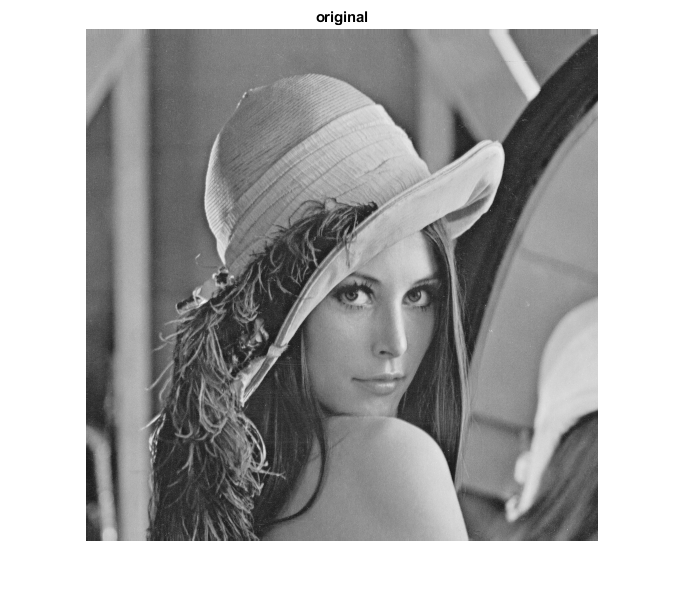

img = imread('Lena_gray.tif');

img_scaled = linearscale(img,0.4,0.5);
matl_scaled = imadjust(img,[0.4 0.5]);

figure
imshow(img);
title('original')

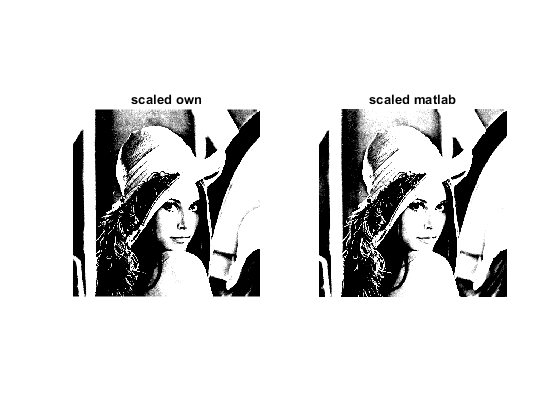


figure
subplot(1,2,1)
imshow(img_scaled);
title('scaled own')
subplot(1,2,2)
imshow(matl_scaled);
title('scaled matlab')

## Question 1.5

Load the data and display the image

clear
im1 = imread('eye.png');

figure
subplot(2,2,1);
image(im1);
axis image
title('original')
subplot(2,2,2);
hist(im1(:),0:255);
axis([0,255,0,22000]);
title('original histogram')

Use slicing and thresholding to get what you want

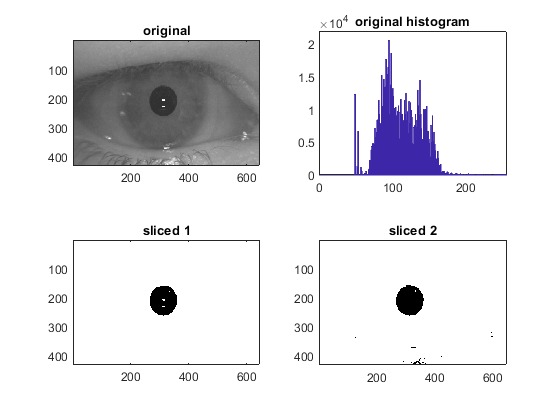

% Modify it further here
thresholded1 = im1>63;
% Display intermediate results
subplot(2,2,3);
image(thresholded1);
axis image
title('sliced 1')

% Modify some more
thresholded2 = im1<204;
sliced2 = thresholded1 & thresholded2;
% Display end result
subplot(2,2,4);
image(sliced2);
axis image
title('sliced 2')

## **Question 1.6**

a) Load the image and determine dimensions

clear
Z = imread('mandrill.bmp');
% Code for finding out dimensions goes here
[~,~,dim_Z] = size(Z)

dim_Z = 1

b) We generate the new variables

im1 = Z(:,:,1);
im2 = Z(:,:,2);

Index in position 3 exceeds array bounds (must not exceed 1).

im3 = Z(:,:,3);
im = double([im1(:) im2(:) im3(:)]);

Figure out the size of the new image

% Code goes here
[~,~,dim_im] = size(im)

*The 3 dimensions in 'Z' are aligned next to each other in columns in 'im', instead of behind each other. So im is a 1 dimenstional matrix with 1 row and 3 columns and each cell consists of an own matrix.*

Determine the size of the original image and put it in nc (number of columns) and nr (number of rows)

% code goes here
[nr, nc, ~] = size(Z)

And now let's try

imRED = reshape(im(:,1), nr, nc);
imGREEN = reshape(im(:,2), nr, nc);
imBLUE = reshape(im(:,3), nr, nc);

d) Display the images

figure
subplot(2,2,1)
image(Z)
axis image
title('original')
subplot(2,2,2)
image(imRED)
colormap gray
axis image
title('imRED')
subplot(2,2,3)
image(imGREEN)
colormap gray
axis image
title('imGREEN')
subplot(2,2,4)
image(imBLUE)
colormap gray
axis image
title('imBlue')

Determine what witchcraft has happened

*So, the R, G and B layers of the original image have been separated and saved into single images (imRED, imGREEN, imBLUE) and then been displayed in grayscale. So basically each new image now displays the pixel intensities of the color specified in the title.*

e) implement the function rgbtohsi.m and test it

% I've programmed it that it works on the images directly
Zhsi=rgbtohsi(Z);
Zhsv_matlab = rgb2hsv(Z);

figure
subplot(1,2,1)
image(Zhsi)
axis image
title('hsi own')
subplot(1,2,2)
image(Zhsv_matlab)
axis image
title('hsv matlab')

## Question 1.7

clear
s=[2 4 8 16 32 64 63 31 15 7 3 1];
f=[2, 2, -2, -2];
% Use the filter function
y1 = filter(f,1,s);

figure
subplot(1,3,1)
plot(0:1:(length(s)-1),s)
title('original signal')
subplot(1,3,2)
plot(0:1:length(s)-1,y1)
title('filter filtered')

Did you expect this result? Did padding take place?

## Question 1.8

Redo it with filtfilt

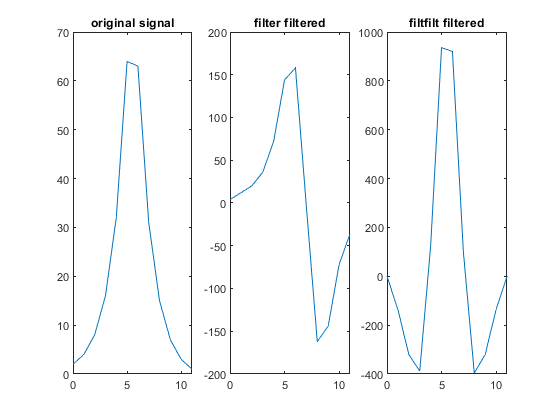

y2 = filtfilt(f,1,s);
subplot(1,3,3)
plot(0:1:length(s)-1,y2)
title('filtfilt filtered')

What does this function do?

## Question 1.9

Load the data

clear
load mandrill

plot it

figure
subplot(1,2,1)
imagesc(X)
colormap gray
axis image

Apply the filter, and plot the result. Ensure that you understand what everything does including the kron command. This is a little piece of Matlab magic

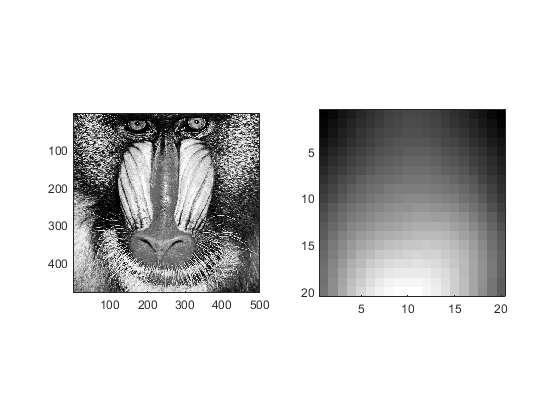

h1=gausswin(20);
h2=kron(h1,h1');
Y = filter2(X,h2);
subplot(1,2,2)
imagesc(Y)
colormap gray
axis image